# Ejercicios simulación discreta

## Ejercicio 1. Crecimiento de poblaciones

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### **1. Planteamiento**

Ecuación del modelo: $P_{n+1} =1\ldotp 13P_n$

Condiciones iniciales: $P_0 =94$

Inicio: $t_0 =2022$    Fin: $t_n =2050$ (por ejemplo)

### **2. Configuración usuario**

Constantes del modelo

% Initial conditions
P0 = 94; % P(0) = 0

% Global constants
tasa_crecimiento = 0.13;

Nombre del modelo

model_name = "Ejer1_CrecimientoPoblaciones";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 2022;
solver.stop = 2050;
solver.step = 1;

Configuración dibujos gráfica

graph = "plot"; % draw function used

% scatter settings
sc = struct();
sc.sz = 200; % size
sc.mkr = "."; % marker
sc.transparency = 0.5; % transparency

% plot settings
pl = struct();
pl.linespec = "-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "t"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "P(t)";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Población de Linces";
labels.title.interpreter = "none";

### 3. Ejecución simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;
    if graph == "scatter"
        scatter(signal.Time, signal.Data, sc.sz, sc.mkr, ...
            MarkerEdgeAlpha=string(sc.transparency), ...
            DisplayName=signal.Name);
    elseif graph == "plot"
        plot(signal.Time, signal.Data, pl.linespec, ...
            MarkerSize=pl.mkr.sz, ...
            DisplayName=signal.Name);
    elseif graph == "none"
        break
    else
        break
    end
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

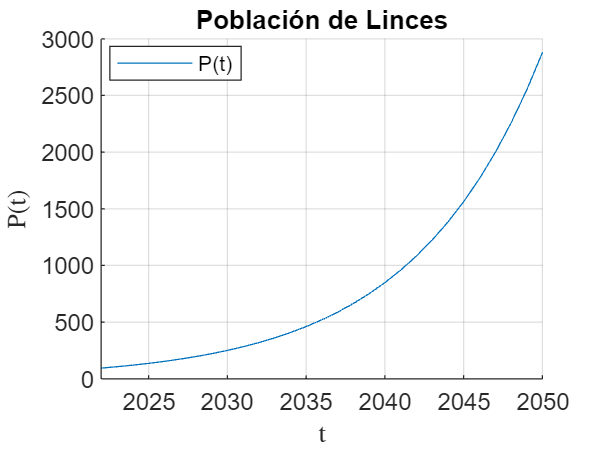

set_labels(labels)
hold off

## Ejercicio 2. Ley de enfriamiento de Newton

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### 1. Planteamiento

Ecuación del modelo: $t_{n+1} =k\;S-\left(k-1\right)\;t_n$

Condiciones iniciales: $t_0 =65\textrm{ºC}$

Inicio: $n_{\textrm{inicio}} =0\;\min$    Fin: $n_{\textrm{fin}} =15\;\min$ 

### 2. Configuración usuario

Constantes del modelo

% Initial conditions
t0 = 65;

% Global constants
k = 1/8;
S = 25;

Nombre del modelo

model_name = "Ejer2_EnfriamientoNewton";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 0;
solver.stop = 15;
solver.step = 1;

Configuración dibujos gráfica

graph = "plot"; % draw function used

% scatter settings
sc = struct();
sc.sz = 200; % size
sc.mkr = "."; % marker
sc.transparency = 0.5; % transparency

% plot settings
pl = struct();
pl.linespec = "-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "tiempo[min]"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "temperatura[Celsius]";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Simulación Enfriamiento";
labels.title.interpreter = "none";

### 3. Ejecución simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;
    if graph == "scatter"
        scatter(signal.Time, signal.Data, sc.sz, sc.mkr, ...
            MarkerEdgeAlpha=string(sc.transparency), ...
            DisplayName=signal.Name);
    elseif graph == "plot"
        plot(signal.Time, signal.Data, pl.linespec, ...
            MarkerSize=pl.mkr.sz, ...
            DisplayName=signal.Name);
    elseif graph == "none"
        break
    else
        break
    end
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

set_labels(labels)
hold off

### 4. Análisis t < 35 ºC

¿En que instante el café tiene una temperatura menor que 35ºC?

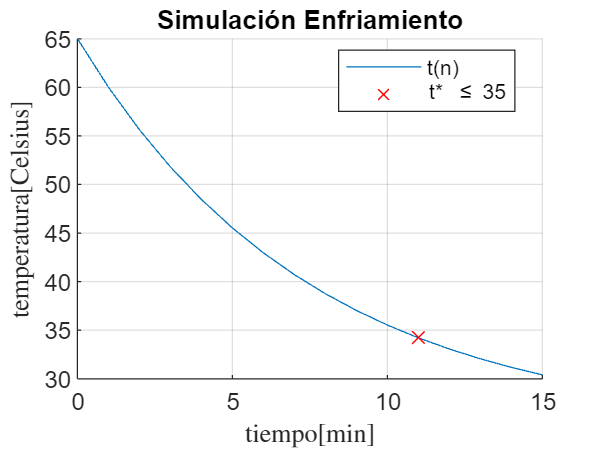

ti = 35;
index = find(signal.Data<ti, 1); % First index of value <= 35
time_i = signal.Time(index);
data_i = signal.Data(index);
hold on
scatter(time_i, data_i, 50, 'rx', ...
    DisplayName="t* \leq 35");
hold off

fprintf("La temperatura es menor que %dºC para\nt >= %d min", ti, time_i)

La temperatura es menor que 35ºC para
t >= 11 min

## Ejercicio 3. Amortización de un préstamo (1)

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### 1. Planteamiento

Ecuación del modelo: $b\left(n\right)=\left(1+i\right)\;b\left(n-1\right)-c_0$

Condiciones iniciales: $b\left(0\right)=15000\;\euro$

Variables:$\textrm{cuota}\;\textrm{mensual}\;\left(c_0 \right)=200\;\euro;\;\textrm{interés}\;\textrm{mensual}\left(i\right)=0\ldotp 01$

Inicio: $t_{\textrm{inicio}} =1º\;\textrm{mes}$ (Para que cuando b(1-1)=b(0) sea el instante inicial)

Fin: $t_{\textrm{fin}} =100º\;\textrm{mes}$

### 2. Configuración usuario

Constantes del modelo

% Initial conditions
b0 = 15000; % b(0) = 15000€

% Global constants
c0 = 200;
it = 0.01;

Nombre del modelo

model_name = "Ejer3_Prestamo";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 0;
solver.stop = 100;
solver.step = 1;

Configuración dibujos gráfica

graph = "plot"; % draw function used

% scatter settings
sc = struct();
sc.sz = 200; % size
sc.mkr = "."; % marker
sc.transparency = 0.5; % transparency

% plot settings
pl = struct();
pl.linespec = "-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "n [meses]"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "b(n) [euros]";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Simulación Balance Préstamo";
labels.title.interpreter = "none";

### 3. Ejecución simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;
    if graph == "scatter"
        scatter(signal.Time, signal.Data, sc.sz, sc.mkr, ...
            MarkerEdgeAlpha=string(sc.transparency), ...
            DisplayName=signal.Name);
    elseif graph == "plot"
        plot(signal.Time, signal.Data, pl.linespec, ...
            MarkerSize=pl.mkr.sz, ...
            DisplayName=signal.Name);
    elseif graph == "none"
        break
    else
        break
    end
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

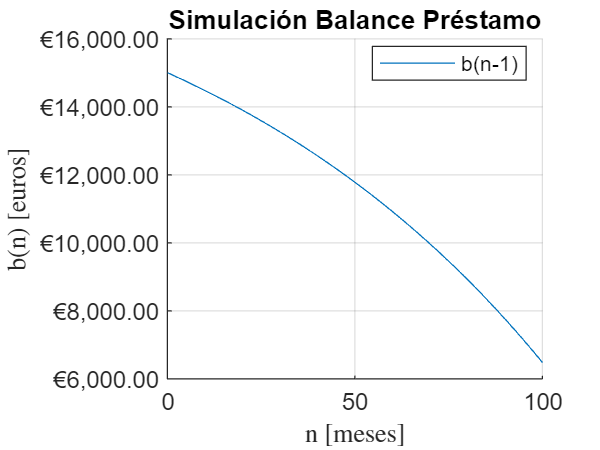

set_labels(labels)
ytickformat('eur')
hold off

### 4. Análisis t = 100 meses (Discreto simple)

capital_inicial = signal.Data(1);
capital_final = signal.Data(end);
fprintf("Capital al principio del mes 0:\n%.2f €", capital_inicial)

Capital al principio del mes 0:
15000.00 €

fprintf("Capital al principio del mes 100:\n%.2f €", capital_final)

Capital al principio del mes 100:
6475.93 €

## Ejercicio 4. Amortización de un préstamo (2)

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### 1. Planteamiento

Ecuación del modelo:


$$b\left(k\right)=b\left(k-1\right)+\int_{T\left(k-1\right)}^{T\left(k\right)} \left\lbrack i\;b\left(k-1\right)-p\right\rbrack \textrm{dt}$$


Condiciones iniciales: $b\left(0\right)=15000\;\euro$

Variables:$\textrm{cuota}\;\textrm{mensual}\;\left(p\right)=200\;\euro;\;\textrm{interés}\;\textrm{mensual}\left(i\right)=0\ldotp 01$

Inicio: $k_{\;inicio} =1º\;mes$ (Para que cuando b(1-1)=b(0) sea el instante inicial)

Fin: $k_{fin} =100º\;mes$

### 2. Configuración usuario

Constantes del modelo

% Initial conditions
b0 = 15000; % b(0) = 15000€

% Global constants
p = 200;
it = 0.01;

Nombre del modelo

model_name = "Ejer4_PrestamoBalance";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 0;
solver.stop = 100;
solver.step = 1;

Configuración dibujos gráfica

graph = "plot"; % draw function used

% scatter settings
sc = struct();
sc.sz = 200; % size
sc.mkr = "."; % marker
sc.transparency = 0.5; % transparency

% plot settings
pl = struct();
pl.linespec = "-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "k [meses]"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "b(k) [euros]";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Simulación Balance Préstamo";
labels.title.interpreter = "none";

### 3. Ejecución simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;
    if graph == "scatter"
        scatter(signal.Time, signal.Data, sc.sz, sc.mkr, ...
            MarkerEdgeAlpha=string(sc.transparency), ...
            DisplayName=signal.Name);
    elseif graph == "plot"
        plot(signal.Time, signal.Data, pl.linespec, ...
            MarkerSize=pl.mkr.sz, ...
            DisplayName=signal.Name);
    elseif graph == "none"
        break
    else
        break
    end
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

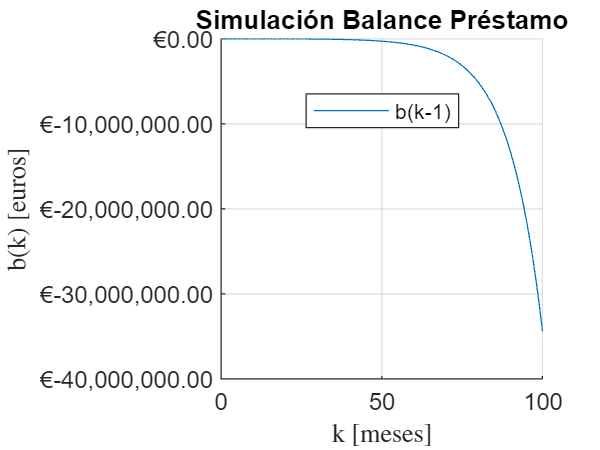

set_labels(labels)
ytickformat('eur')
hold off

### 4. Análisis t = 100 meses (Fórmula con integrador de señal discreto)

capital_inicial = signal.Data(1);
capital_final = signal.Data(end);
fprintf("Capital al principio del mes 0:\n%.2f €", capital_inicial)

Capital al principio del mes 0:
15000.00 €

fprintf("Capital al principio del mes 100:\n%.2f €", capital_final)

Capital al principio del mes 100:
-34431530.92 €

## Ejercicio 5. Ecuación en diferencias

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### 1. Planteamiento

Ecuación del modelo: $y\left(k+2\right)=-y\left(k\right)$

Condiciones iniciales: $y\left(0\right)=1;\;y\left(1\right)=0$

Inicio: $t_{\textrm{inicio}} =0$    Fin: $t_{\textrm{fin}} =5$ (por ejemplo)

### 2. Configuración usuario

Constantes del modelo

% Initial conditions
y0 = 0; % y(0) = 1
y1 = 1; % y(1) = 0

Nombre del modelo

model_name = "Ejer5_EcDiferencias";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 0;
solver.stop = 20;
solver.step = 1;

Configuración dibujos gráfica

graph = "scatter"; % draw function used

% scatter settings
sc = struct();
sc.sz = 200; % size
sc.mkr = "."; % marker
sc.transparency = 0.5; % transparency

% plot settings
pl = struct();
pl.linespec = "-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "n"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "Fib(n)";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Simulación Fibonacci";
labels.title.interpreter = "none";

### 3. Ejecución simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;
    if graph == "scatter"
        scatter(signal.Time, signal.Data, sc.sz, sc.mkr, ...
            MarkerEdgeAlpha=string(sc.transparency), ...
            DisplayName=signal.Name);
    elseif graph == "plot"
        plot(signal.Time, signal.Data, pl.linespec, ...
            MarkerSize=pl.mkr.sz, ...
            DisplayName=signal.Name);
    elseif graph == "none"
        break
    else
        break
    end
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

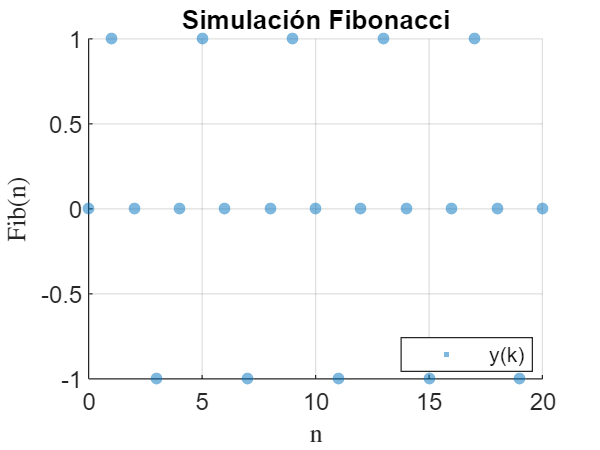

set_labels(labels)
hold off

## Ejercicio 6. Sistema con limitación en la fuente

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### 1. Planteamiento

Ecuación del modelo: $k\;y_{k+1} =1+\left(k-1\right)y_{k-1}$ que equivale a $y_{k+1} =\frac{1+\left(k-1\right)y_{k-1} }{k}$

Condiciones iniciales: iguales a cero

Inicio: $k_{inicial} =4$    Fin: $k_{final} =10$ (por ejemplo)

Adicionalmente: $k>3$

### 2. Configuración usuario

Constantes del modelo

% Initial conditions
y0 = 0; % y(0) = 0
y1 = 0; % y(1) = 0

Nombre del modelo

model_name = "Ejer6_LimitacionFuente";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 1;
solver.stop = 100;
solver.step = 1;

Configuración dibujos gráfica

graph = "plot"; % draw function used

% scatter settings
sc = struct();
sc.sz = 200; % size
sc.mkr = "."; % marker
sc.transparency = 0.5; % transparency

% plot settings
pl = struct();
pl.linespec = "-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "k"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "y(k)";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Simulación con limitación en fuente";
labels.title.interpreter = "none";

### 3. Ejecución simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;
    if graph == "scatter"
        scatter(signal.Time, signal.Data, sc.sz, sc.mkr, ...
            MarkerEdgeAlpha=string(sc.transparency), ...
            DisplayName=signal.Name);
    elseif graph == "plot"
        plot(signal.Time, signal.Data, pl.linespec, ...
            MarkerSize=pl.mkr.sz, ...
            DisplayName=signal.Name);
    elseif graph == "none"
        break
    else
        break
    end
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

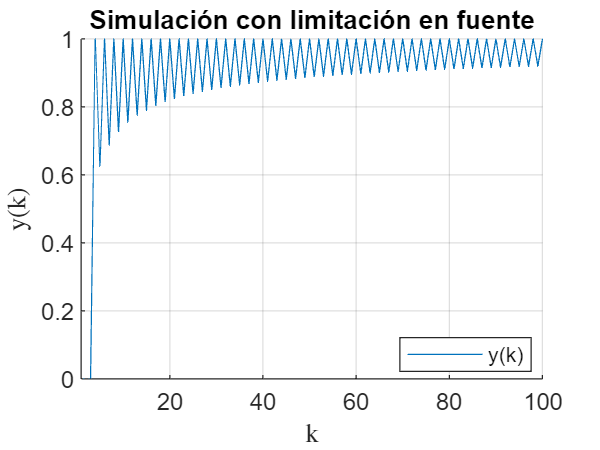

set_labels(labels)
hold off

# Plantilla Simulink

**Limpieza del entorno de trabajo**

clear % clear workspace variables
clc % clear command line
close all % close all figures
beep off % Supress running model sound

**Resumen**

Este script configura los principales parámetros de simulación, dibujo y etiquetas de un modelo discreto para su posterior ejecución y análisis.

### 1. Planteamiento

Ecuación del modelo: $\textrm{Fib}\left(n+1\right)=\textrm{Fib}\left(n\right)+\textrm{Fib}\left(n-1\right)$

Condiciones iniciales: $\textrm{Fib}\left(0\right)=0;\;\textrm{Fib}\left(1\right)=1$

Inicio: $n_0 =0$    Fin: $n_1 =5$ (por ejemplo)

### 2. Configuración usuario

Constantes del modelo

% Initial conditions
F0 = 0; % F(0) = 0
F1 = 1; % F(1) = 1

% Global constants
% Example: g = 9.8

Nombre del modelo

model_name = "modelo_fibonacci";

Configuración del solver

solver = struct();
solver.type = "Fixed-Step";
solver.name = "FixedStepDiscrete";
solver.start = 0;
solver.stop = 5;
solver.step = 1;

Configuración dibujos gráfica

graph = "scatter"; % draw function used

% scatter settings
sc = struct();
sc.sz = 200; % size
sc.mkr = "."; % marker
sc.transparency = 0.5; % transparency

% plot settings
pl = struct();
pl.linespec = "-"; % linestyle/marker/color
pl.mkr.sz = 12; % marker size

Configuración etiquetas gráfica

labels = struct();
% xlabel settings
labels.x.name = "n"; 
labels.x.interpreter = "latex";

% ylabel settings
labels.y.name = "Fib(n)";
labels.y.interpreter = "latex";

% title settings
labels.title.name = "Simulación Fibonacci";
labels.title.interpreter = "none";

### 3. Ejecución simulación

Al final de este livescript se encuentra la definición de la función sim_config, función que simula el modelo de nombre model_name para una configuración de solver almacenada en el struct solver

sim_data = sim_config(model_name, solver); % End of file definition

De sim_data se extrae la información de la simulación gracias a bloques output (véase consideraciones adicionales Simulink al final de este LiveScript)

Obtenemos un data set con las señales del campo yout

signals = sim_data.yout; % Dataset container of signals
num_signals = numElements(signals); % Number of signals

Se dibuja cada señal

% Draw each signal
hold on
for i = 1:num_signals
    signal = signals{i}.Values;
    if graph == "scatter"
        scatter(signal.Time, signal.Data, sc.sz, sc.mkr, ...
            MarkerEdgeAlpha=string(sc.transparency), ...
            DisplayName=signal.Name);
    elseif graph == "plot"
        plot(signal.Time, signal.Data, pl.linespec, ...
            MarkerSize=pl.mkr.sz, ...
            DisplayName=signal.Name);
    elseif graph == "none"
        break
    else
        break
    end
end
grid on

Límites y leyenda

xlim([signal.Time(1), signal.Time(end)]);
legend('show','location','best');

Al final de este livescript se define la función set_labels que crea las etiquetas a partir de la configuración

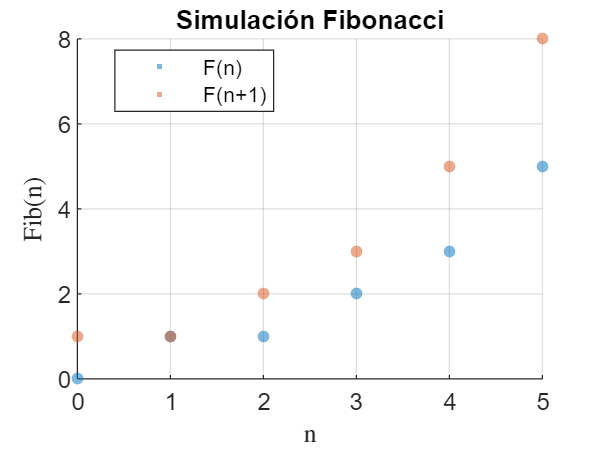

set_labels(labels)
hold off

### ***Funciones disponibles para todas las secciones***

MATLAB permite utilizar la última sección de un livescript para definir funciones globales.

#### *Decorador de la función sim de MATLAB

Esta función ejecuta la función sim, tras establecer los parámetros del solver. Recibe como argumentos el nombre del modelo y un struct con la configuración del solver.

function sim_data = sim_config(model_name, solver)

Carga del modelo con load_system

load_system(model_name)
% open_system(model_name) will also open it

Configuración con set_param

% Set solver parameters
set_param(model_name, ...
    SolverType  = solver.type, ...
    SolverName  = solver.name, ...
    StartTime   = string(solver.start),...
    StopTime    = string(solver.stop), ...
    FixedStep   = string(solver.step) ...
    )
% More model parameters can be retrieved with:
% model_data = get_param(model_name, "ObjectParameters")
% Access blocks params with "model_name/block_name"

Simulación del modelo con sim

sim_data = sim(model_name);
% SimulationMode="normal" by default
end

#### *Configuración xlabel, ylabel, title de MATLAB

Esta función configura las etiquetas de la figura actual. Recibe una variable struct con la configuración de las etiquetas.

function set_labels(labels)
title(labels.title.name, Interpreter=labels.title.interpreter)
xlabel(labels.x.name, Interpreter=labels.x.interpreter);
ylabel(labels.y.name, Interpreter=labels.y.interpreter);
end

#### Consideraciones adicionales Simulink

Se utiliza el bloque Out1 para cada señal debido a que:

- No usaremos bloques Bus para no formatear los nombres, ejemplo: MATLAB transforma '+' a '_'

- No usaremos bloques To Workspace para iterar más fácil, iteramos el contenido de .yout

- Es posible el manejo de múltiples condiciones iniciales sin problema

#### Scripts adicionales

Para obtener cada señal se puede usar: 

% signals{index}
% signals.getElement('signal_name')

Los valores de una señal se encuentran en el campo Values

% signals{index}.Values.Data
% signals{index}.Values.Time
% signals{index}.Values.Name

Inicio y fin de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% start_value = signals{1}.Values.Data(1);
% end_value = signals{1}.Values.Data(end);

Máximo y mínimo de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% [signal_max, index_max] = max(signals{1}.Values.Data);
% point_max = [signals{1}.Values.Time(index_max), signal_max];
%
% [signal_min, index_min] = min(signals{1}.Values.Data);
% point_min = [signals{1}.Values.Time(index_min), signal_min];

Media de una señal

% sim_data = sim_config(model_name, solver)
% signals = sim_data.yout
%
% signal_mean = mean(signals{1}.Values.Data)

Autor: Alfredo Robledano Abasolo 3ºB Ingeniería Matemática UFV (2023-2024)